# Linear Regression and Polyfit

In this notebook, we will:

- Learn how to import data from a .csv file

- Gain a conceptual understanding of linear regression

- Find the best fit line for data

- Find the best fit curve for data using `polyfit.`

## Importing Data 

In practice, when you scrape tabular data from a source, you typically save it in as **comma separated value** file. When you analyze it, you'll want to import it into MATLAB and store it in an array so that you can perform various operations and analyses on the data. 

In this notebook, we are going to try to find the best fit line for some penguin data. But first we need to import the data. You'll notice that our folder contains a file called `penguins.csv`. You can import the data from a .csv file using the following command:

`table_name = readtable("filename.csv")`

In the code chunk below, import the data from `penguins.csv`. Store your data in a table called `penguin_table.`

%% Code here.

penguin_table = readtable("penguins.csv");
head(penguin_table)

ans = 8×8 table
     species         island        bill_length_mm    bill_depth_mm    flipper_length_mm    body_mass_g       sex        year
    __________    _____________    ______________    _____________    _________________    ___________    __________    ____

    {'Adelie'}    {'Torgersen'}         39.1             18.7                181              3750        {'male'  }    2007
    {'Adelie'}    {'Torgersen'}         39.5             17.4                186              3800        {'female'}    2007
    {'Adelie'}    {'Torgersen'}         40.3               18                195              3250        {'female'}    2007
    {'Adelie'}    {'Torgersen'}         36.7             19.3                193      

Once we've read in the data, we can read off specific columns and/or rows using indexing similar to what we did for arrays. In addition, if we want to know all of the column headings in a table, we can use the command

`head(table_name)`

which will give us just the first 8 rows of the table. This gives you a tiny glimpse of what the table looks like, including any categories. 

Use the code chunk below to extract the 215th row of `penguin_table.`

%% Code here.

penguin_table(215,:)

ans = 1×8 table
     species        island      bill_length_mm    bill_depth_mm    flipper_length_mm    body_mass_g      sex       year
    __________    __________    ______________    _____________    _________________    ___________    ________    ____

    {'Gentoo'}    {'Biscoe'}         54.3             15.7                231              5650        {'male'}    2008


Depending on the type of analysis we wish to do, we can convert our table to an array using `table2array(table_name)`. Once you do this, you have all of the privileges of being an array, and can perform array operations. Furthermore, you can extract out rows/columns of the array and store those as vectors. 

In the code chunk below, try to create an array of the penguin data and store it in a variable called `penguin_array`. What happens?

%% Code here.

%penguin_array = table2array(penguin_table)


We encountered an error because all of the entries in an array need to be of the same type. Instead, let's create an array called `penguin_array` that just consists of the columns with numeric entries. **Be sure to comment out the erroneous line of code above first. **

Hint: Visit this documentation page to see how you can extract columns that aren't consecutive:

[https://www.mathworks.com/help/matlab/matlab_prog/access-data-in-a-table.html](https://www.mathworks.com/help/matlab/matlab_prog/access-data-in-a-table.html)

%% Code here.

penguin_array = table2array(penguin_table(:, {'bill_length_mm','bill_depth_mm','body_mass_g' ...
    'flipper_length_mm', 'body_mass_g', 'year'}))

penguin_array = 	1.0e+03 *

    0.0391    0.0187    3.7500    0.1810    3.7500    2.0070
    0.0395    0.0174    3.8000    0.1860    3.8000    2.0070
    0.0403    0.0180    3.2500    0.1950    3.2500    2.0070
    0.0367    0.0193    3.4500    0.1930    3.4500    2.0070
    0.0393    0.0206    3.6500    0.1900    3.6500    2.0070
    0.0389    0.0178    3.6250    0.1810    3.6250    2.0070
    0.0392    0.0196    4.6750    0.1950    4.6750    2.0070
    0.0341    0.0181    3.4750    0.1930    3.4750    2.0070
    0.0420    0.0202    4.2500    0.1900    4.2500    2.0070
    0.0378    0.0171    3.3000    0.1860    3.3000    2.0070


Now you can perform any array operations you might need on `penguins_array.`

In the code chunk below, create two new vectors:

- `flipper_length`, consisting of the column `flipper_length_mm`

- `weight, `consisting of the column `body_mass_g`

%% Code here.

flipper_length = table2array(penguin_table(:,'flipper_length_mm'))

flipper_length =    181
   186
   195
   193
   190
   181
   195
   193
   190
   186


weight = table2array(penguin_table(:,'body_mass_g'))

weight =         3750
        3800
        3250
        3450
        3650
        3625
        4675
        3475
        4250
        3300


Finally, create a scatter plot of `flipper_length` against `weight`. Add labels and a title to your graph. 

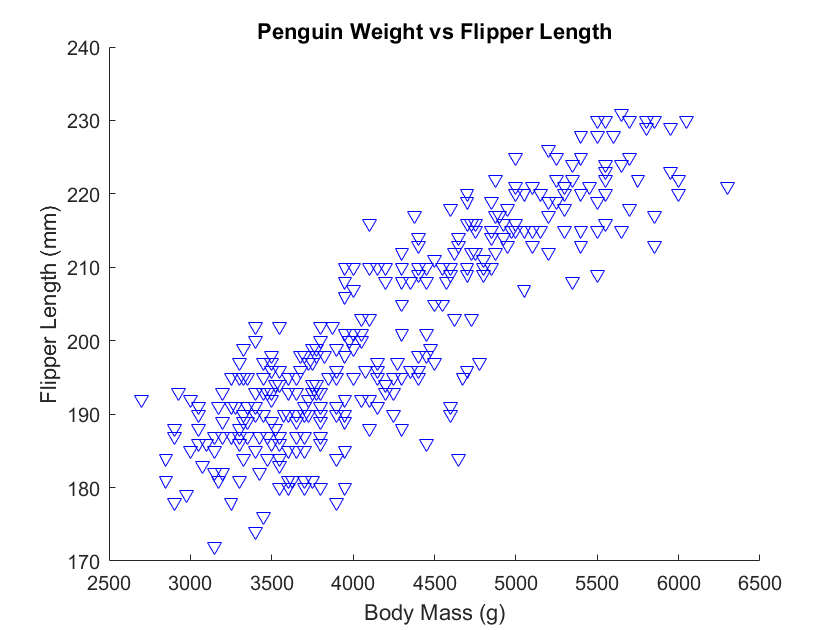

%% Code here.


scatter(weight, flipper_length,'bv')
title("Penguin Weight vs Flipper Length")
xlabel("Body Mass (g)")
ylabel("Flipper Length (mm)")

## Two-Variable Linear Regression

Looking at our plot it seems that we can predict a penguin's flipper length from its body mass. In general, a **data model **or just **model** is a mathematical and/or statistical relationship between variables. For example, if the relationship is a line, the model looks like $y = mx + b$ for variables $x$ and $y$. 

**Linear regression **is a process by which we fit a linear model to data. In two-variable linear regression, we have one *input* or *predictor* variable, and one *output* or *response* variable. In the case of the penguin data, `weight` is our predictor variable and `flipper_length` is our response variable. 

Suppose we have $n$ observations of `weight` and `flipper_length`. Then we have $n$ observed data points $(x_1, y_1), (x_2, y_2), \ldots (x_n, y_n)$. The linear regression model is $y = \beta_0 + \beta_1x + \epsilon$ with $y_i = \beta_0 + \beta_1x_i + \epsilon_i$. Note that $\epsilon_i$ is just an error term, and the best possible model minimizes this error. 

Ideally, we would be able to find $\beta_0$ and $\beta_1$ such that

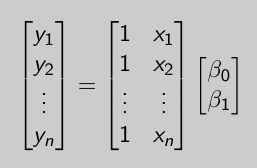

where $y_i$ are the actual response values and the $x_i$ are our predictor values. However, realistically we can't find such a perfect line (and if we could, it probably wouldn't be modeling a real process). What we can do, is find $\beta_0$ and $\beta_1$ that minimize the error between the left side of the equation (actual observed values) and the right side of the equation (the output of the model). Think "collective closeness."

We use a function called **root mean squared error (RMSE) **to determine closeness of a line to data, or **goodness of fit**. The RMSE is defined as:


$$RMSE = \displaystyle\sqrt{\frac{1}{n}\sum_{i=1}^n (\beta_0 + \beta_ix_i - y_i)$$


The "best" choice of $\beta_0$ and $\beta_1$ are those that minimize the RMSE. There exists a formula for this minimum, but we won't get into that in this minicourse. For now, we can just rely on MATLAB to do this calculus for us. Let's see how this is done using the `penguins` dataset. 

Start by setting up a column vector `y` containing all of the flipper lengths, and a vector `X` containing the penguin weights padded by a column of ones. 

Hint: What command can you use to easily create a column of ones?

%% Code here. 

len_weight = length(weight)

len_weight = 342


y = flipper_length

y =    181
   186
   195
   193
   190
   181
   195
   193
   190
   186


X = ones(len_weight, 1)

X =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


X(:,2) = weight

X =            1        3750
           1        3800
           1        3250
           1        3450
           1        3650
           1        3625
           1        4675
           1        3475
           1        4250
           1        3300


Next, solve for $\beta_0$ and $\beta_1$ using the `\` command. Store your answer in a vector called `beta.`

%% Code here.

beta = X\y

beta =   136.7296
    0.0153


The first entry of this column vector is $\beta_0$, or the $y$-intercept of the line. The second entry is $\beta_1$, or the slope of your line. Using this information, create a scatter plot of the penguins data, against linear regression model you just found. Give your plot a title and labels. 

Hint: You might have to use `xlim` and `ylim` to adjust your axes.

%% Code here.











In practice, if you are working with a huge dataset, you can use MATLAB's built-in `fitlm` to do this process directly from the table, but you would need to download the Statistics and Machine Learning Toolbox. This function also gives you some extra, fancy statistical info that we won't discuss in this minicourse. Here is an example of how that would look on our Penguins dataset.

%% Don't run this code unless you have the Statistics and ML Toolbox.

%lm = fitlm(penguin_table, 'flipper_length_mm~body_mass_g')


## `polyfit`

If your data isn't linear, you can use `polyfit` to do a similar process. You can read about the machinery behind `polyfit` here: 

[https://www.mathworks.com/help/matlab/ref/polyfit.html](https://www.mathworks.com/help/matlab/ref/polyfit.html)

For now, here is an example of fitting a polynomial to some imaginary data. We start by looking at the scatter plot of data.

%% I am just creating some random data points

poly_x = linspace(0,5,50)
poly_y = 2*(poly_x).^2 - poly_x + (2*rand(1,50)-1)
scatter(poly_x, poly_y, 'b*') 


Let's say we decide a degree-2 polynomial would be the most desirable. We call `polyfit` on the data:

%% Find a degree-2 polynomial that fits this data

coeffs = polyfit(poly_x, poly_y, 2)

This tells us that the best polynomial that fits our data is $1.9680x^2 -0.8148x-0.2584$. Let's plot it just to check!

%% Check that our polynomial fits our data

%hold on 

%plot(poly_x, coeffs(1)*poly_x.^2 + coeffs(2)*poly_x + coeffs(3))

%% remember that coeffs(n) extracts the nth entry of coeffs.

%hold off

## Disclaimers and References

*This notebook was written for the *[*The EDGE Program*](https://www.edgeforwomen.org/)* by Anila Yadavalli, Ph. D., 2021.*

*Redistribution of the material contained in this repository is conditional on acknowledgement of Anila Yadavalli, Ph.D.'s original authorship. *

*The Penguins dataset was obtained from *[https://allisonhorst.github.io/palmerpenguins/](https://allisonhorst.github.io/palmerpenguins/)